# Fuzzy Logic Control for House Heating System

## **House Heating System**

model = "houseHeatingSystemWithFuzzyControl";
open_system(model)

open_system(model+"/House Thermal Network")
open_system(model+"/Heater")

## **FIS for Calculating Desired Room Temperature**

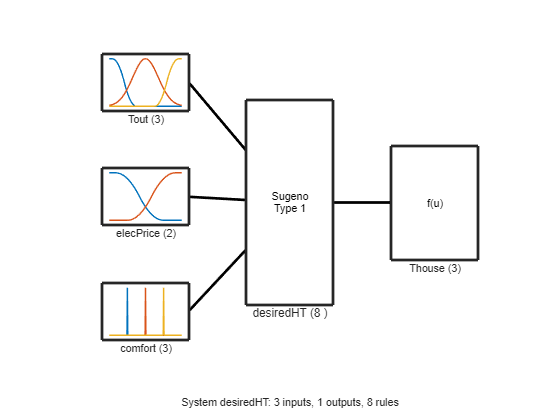

desiredHT = sugfis(Name="desiredHT");
desiredHT = addInput(desiredHT,[4 12],Name="Tout");
desiredHT = addMF(desiredHT,"Tout","zmf",[4.333 7],Name="low");
desiredHT = addMF(desiredHT,"Tout","gaussmf",[1.416 8],Name="medium");
desiredHT = addMF(desiredHT,"Tout","smf",[9 11.67],Name="high");
desiredHT = addInput(desiredHT,[0 0.15],Name="elecPrice");
desiredHT = addMF(desiredHT,"elecPrice", ...
    "zmf",[0.0125 0.1125],Name="low");
desiredHT = addMF(desiredHT,"elecPrice", ...
    "smf",[0.0375 0.1375],Name="high");
desiredHT = addInput(desiredHT,[0 4],Name="comfort");
desiredHT = addMF(desiredHT,"comfort","" + ...
    "trimf",[1 1 1],Name="minC");
desiredHT = addMF(desiredHT,"comfort", ...
    "trimf",[2 2 2],Name="varC");
desiredHT = addMF(desiredHT,"comfort", ...
    "trimf",[3 3 3],Name="maxC");
desiredHT = addOutput(desiredHT,[19 23],Name="Thouse");
desiredHT = addMF(desiredHT,"Thouse", ...
    "constant",20,Name="low");
desiredHT = addMF(desiredHT,"Thouse", ...
    "constant",21,Name="medium");
desiredHT = addMF(desiredHT,"Thouse", ...
    "constant",22,Name="high");
desiredHT = addRule(desiredHT,[ ...
    "Tout==low & elecPrice==low & comfort==varC => Thouse=medium (1)"; ...    
    "Tout==medium & elecPrice==low & comfort==varC => Thouse=medium (1)" ; ...
    "Tout==high & elecPrice==low & comfort==varC => Thouse=high (1)"; ...
    "Tout==low & elecPrice==high & comfort==varC => Thouse=low (1)"; ...
    "Tout==medium & elecPrice==high & comfort==varC => Thouse=medium (1)"; ...
    "Tout==high & elecPrice==high & comfort==varC => Thouse=medium (1)"; ...
    "comfort==minC => Thouse=low (1)"; ...
    "comfort==maxC => Thouse=high (1)" ...
    ]);
figure
plotfis(desiredHT)

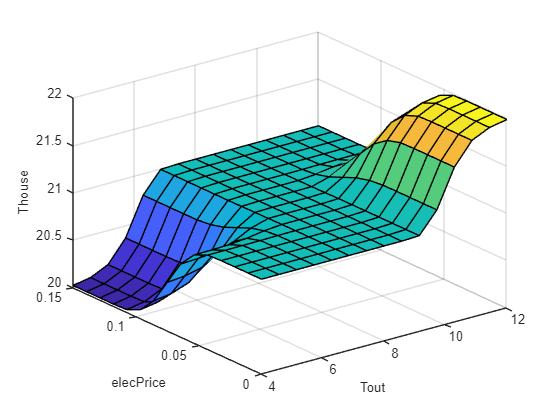

figure
gensurf(desiredHT)

## **Fuzzy PID Controller**

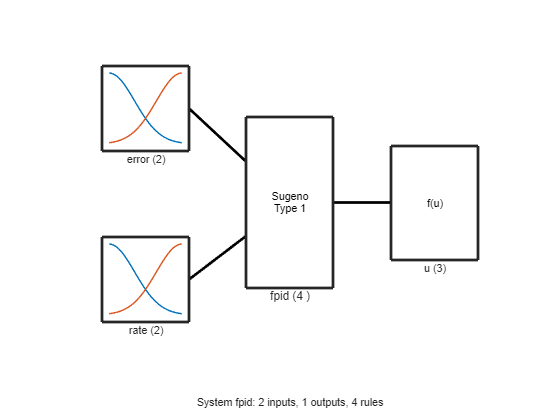

fpid = sugfis(Name="fpid");
fpid = addInput(fpid,[-1 1],Name="error");
fpid = addMF(fpid,"error", ...
    "gaussmf",[0.7 -1],Name="negative");
fpid = addMF(fpid,"error", ...
    "gaussmf",[0.7 1],Name="positive");
fpid = addInput(fpid,[-1 1],Name="rate");
fpid = addMF(fpid,"rate", ...
    "gaussmf",[0.7 -1],Name="negative");
fpid = addMF(fpid,"rate", ...
    "gaussmf",[0.7 1],Name="positive");
fpid = addOutput(fpid,[-2 2],Name="u");
fpid = addMF(fpid,"u", ...
    "constant",-2,Name="negative");
fpid = addMF(fpid,"u", ...
    "constant",0,Name="zero");
fpid = addMF(fpid,"u", ...
    "constant",2,Name="positive");
fpid = addRule(fpid,[ ...
    "error==negative & rate==negative => u=negative (1)"; ...
    "error==positive & rate==negative => u=zero (1)"; ...
    "error==negative & rate==positive => u=zero (1)"; ...
    "error==positive & rate==positive => u=positive (1)"]);
figure
plotfis(fpid)

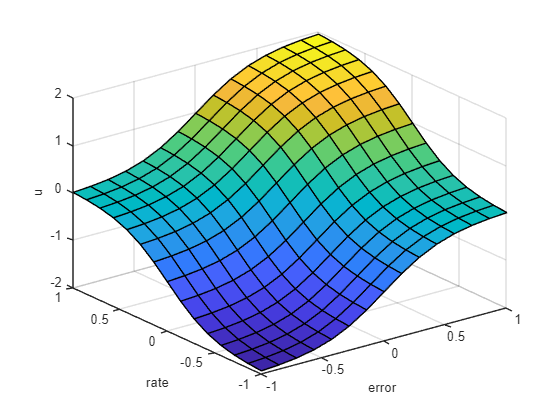

figure
gensurf(fpid)

## Comfort Level Simulation Results

set_param(model+"/Comfort/Level","Value","1")
sim(model)

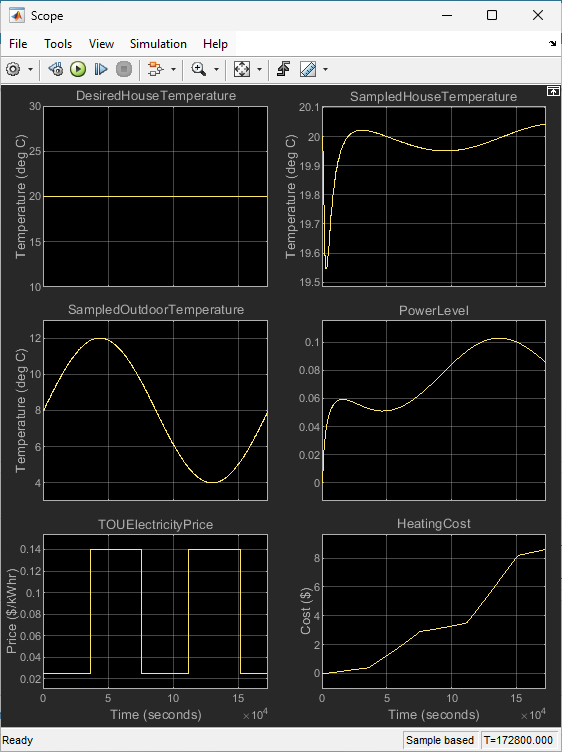

set_param(model+"/Comfort/Level","Value","2")
sim(model)

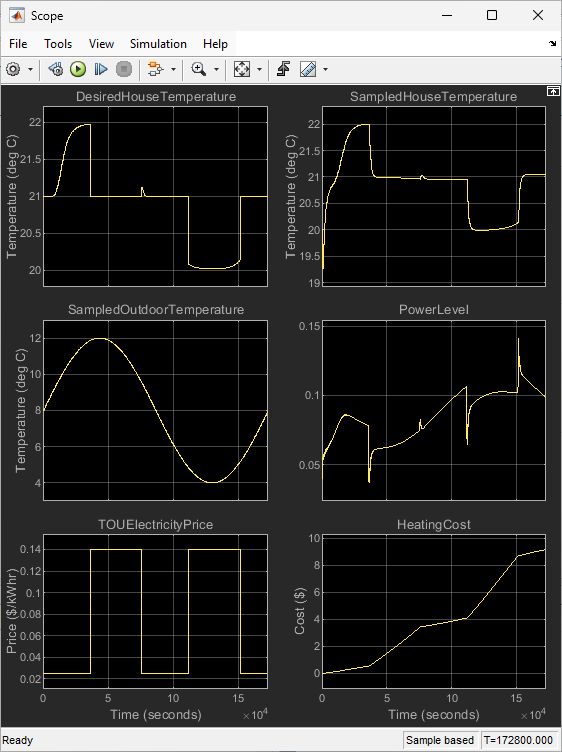

set_param(model+"/Comfort/Level","Value","3")
sim(model)

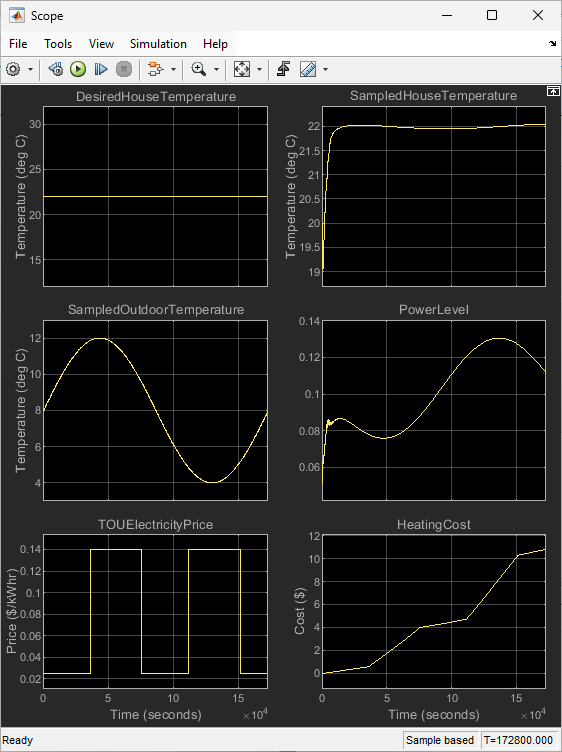

## Other Control Strategies

desiredHT.Rules(1).Description = ...
    "Tout==low & elecPrice==low & comfort==varC => Thouse=low (1)";
desiredHT.Rules(5).Description = ...
    "Tout==medium & elecPrice==high & comfort==varC => Thouse=low (1)";
disp([desiredHT.Rules(1:6).Description]')

    "Tout==low & elecPrice==low & comfort==varC => Thouse=low (1)"
    "Tout==medium & elecPrice==low & comfort==varC => Thouse=medium (1)"
    "Tout==high & elecPrice==low & comfort==varC => Thouse=high (1)"
    "Tout==low & elecPrice==high & comfort==varC => Thouse=low (1)"
    "Tout==medium & elecPrice==high & comfort==varC => Thouse=low (1)"
    "Tout==high & elecPrice==high & comfort==varC => Thouse=medium (1)"



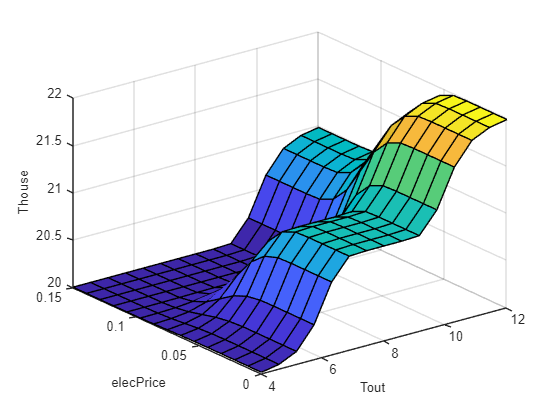

figure
gensurf(desiredHT)

set_param(model+"/Comfort/Level","Value","2")
sim(model)